# Tema 5 - Integración Numèrica (IV) 

### Matlab - Trapezis

Consulta la documentació i exemples de [trapz](https://es.mathworks.com/help/matlab/ref/trapz.html) i l'exemple de [integració de dades numèriques](https://es.mathworks.com/help/matlab/math/integration-of-numeric-data.html)

### Matlab - Romberg

Podeu fer ús dels codis de Matlab File Exchange, [codis](https://es.mathworks.com/matlabcentral/fileexchange/58286-romberg) 

### Matlab - Integració adaptativa

% fplot(@(x)humps(x),[0,1]),title('funció humps')
% valor = integral(@(x)humps(x),0,1,'RelTol',1e-8,'AbsTol',1e-13);
% fprintf('integral_valor numèric = %0.12f\t',valor);
% quadgui(@(x)humps(x),0,1,1.0e-3)

## Mètode de Montecarlo

f = @(x)x;
a = 0; b = 1;
integral(f,a,b)   % valor

ans = 0.5000

k=0;
m=10000;
P =[];
for n=1:m
    x = rand;
    y = rand;
    if y <= f(x) 
        k = k+1;
        P = [P;x,y];
    end
end
valor_aprox = k/m

valor_aprox = 0.4985

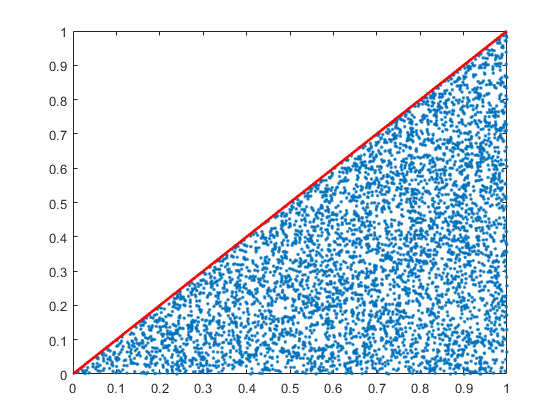

t = a:0.05:b; yt = f(t);
plot(P(:,1),P(:,2),'.',t,yt,'r','LineWidth',2)

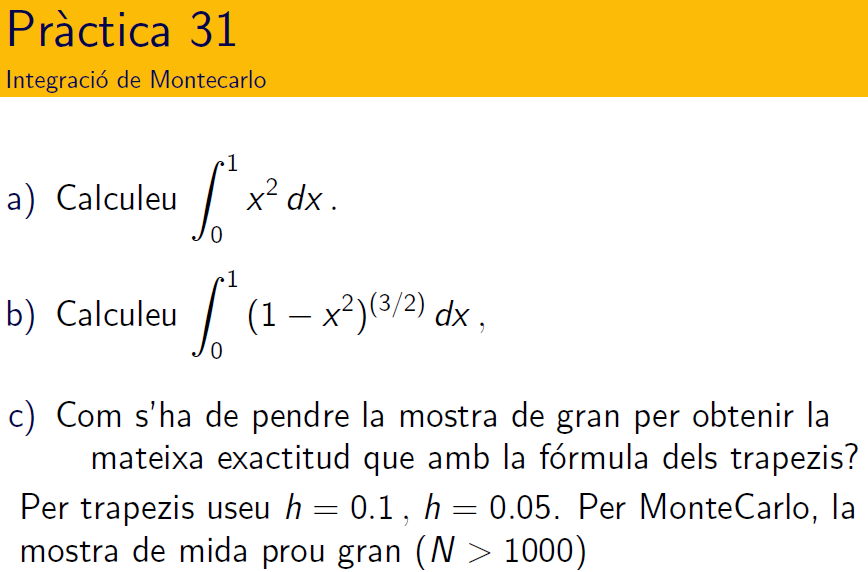

### 
$$\quad a)\quad \int_0^1 x^2 dx = \frac{1}{3}$$
 

ve = integral(@(x)x.^2,0,1);   % valor exacte
fprintf('integral valor numèric exacte = %0.12f\t',ve);

integral valor numèric exacte = 0.333333333333	

### 
$$\quad b)\quad \int_0^1 (1-x^2)^{3/2} dx = \frac{3\pi}{16}$$
 

% syms t, int(@(t)(1-t.^2).^(3/2),t),int(@(t)(1-t.^2).^(3/2),t,0,1),double(ans)
ve = integral(@(x)(1-x.^2).^(3/2),0,1);   % valor exacte
fprintf('integral valor numèric exacte = %0.6f\t',ve);

integral valor numèric exacte = 0.589049	

integral_simulacio  =  0.589380	 tamany mostra = 100000	 decimals correctes = 3


integral_trapezis  =  0.588815	 h = 0.10	 decimals correctes = 3


integral_trapezis  =  0.589008	 h = 0.05	 decimals correctes = 4
